# Script to find CCEPs, characterize height, prominance, half width max

Switch in polarity? 

half width?

prominance?

close all;clearvars; clc

Z_ConstantsLarryDavidStephen;

sid = input('what is the SID?\n','s');

load(fullfile(META_DIR, [sid '_StimulationAndCCEPs']));


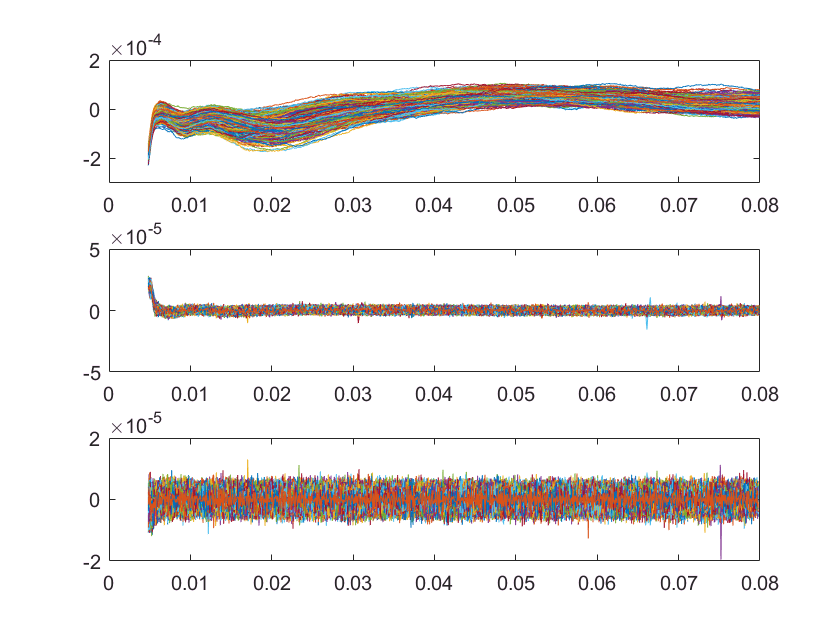

% look at electrode of interest .
% for 0b5a2e it'll be 14 to start  , also look at 31 and 23 

% try setting t_new based off of how long the issues seem to be 
figure
t_new = t(t>0.004833 & t < 0.08);
data = ECoGData((t>0.004833 & t<0.08),:,23);
ax1  = subplot(3,1,1);
plot(t_new,data);
ylim([-300e-6 200e-6])

ax2 = subplot(3,1,2);
data_deriv = diff(data);
plot(t_new(1:end-1),data_deriv);


ax3 = subplot(3,1,3);
data_deriv_2 = diff(data_deriv);
plot(t_new(1:end-2),data_deriv_2);

linkaxes([ax1,ax2,ax3],'x')

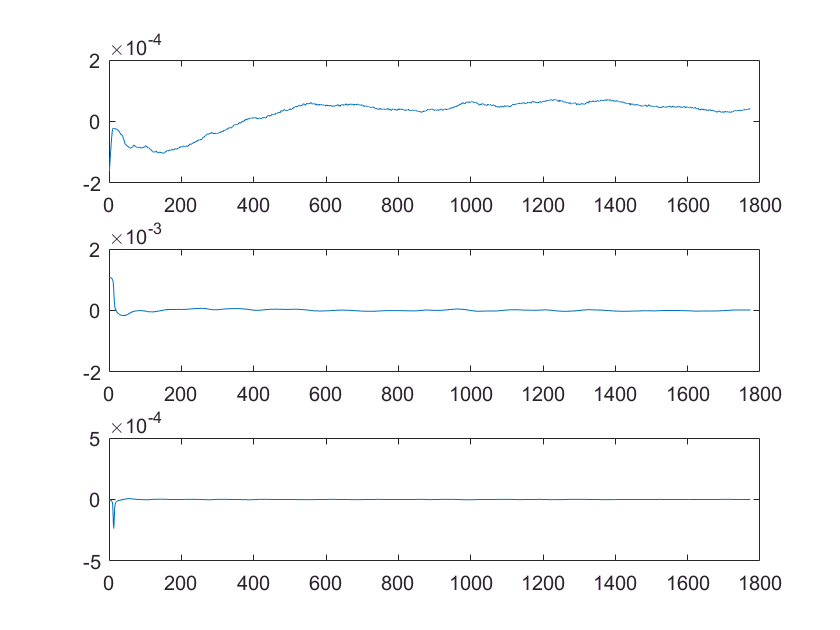

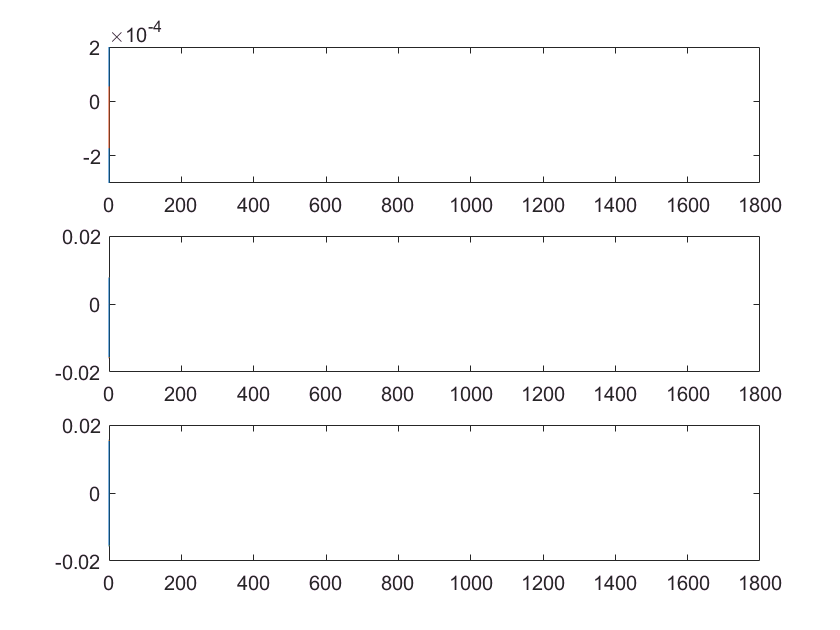

% TV reg diff
% TVRegDiff( noisyabsdata, 500, 0.2, [], 'small', 1e-6, 0.01, 1, 0 )
data_derivT = [];
data_sub = data(:,1000);

%data_deriv= TVRegDiff(data_sub,500,50,[],'small',1e-9,0.01,1,0);
data_deriv= TVRegDiff(data_sub,50,0.00002,[],'small',1e-6,0.01,0,0);


data_deriv_2 = diff(data_deriv);

figure
ax1  = subplot(3,1,1);
plot(data_sub);
ylim([-200e-6 200e-6]);

ax2 = subplot(3,1,2);
plot(data_deriv);

ax2 = subplot(3,1,3);
plot(data_deriv_2);


linkaxes([ax1,ax2,ax3],'x');

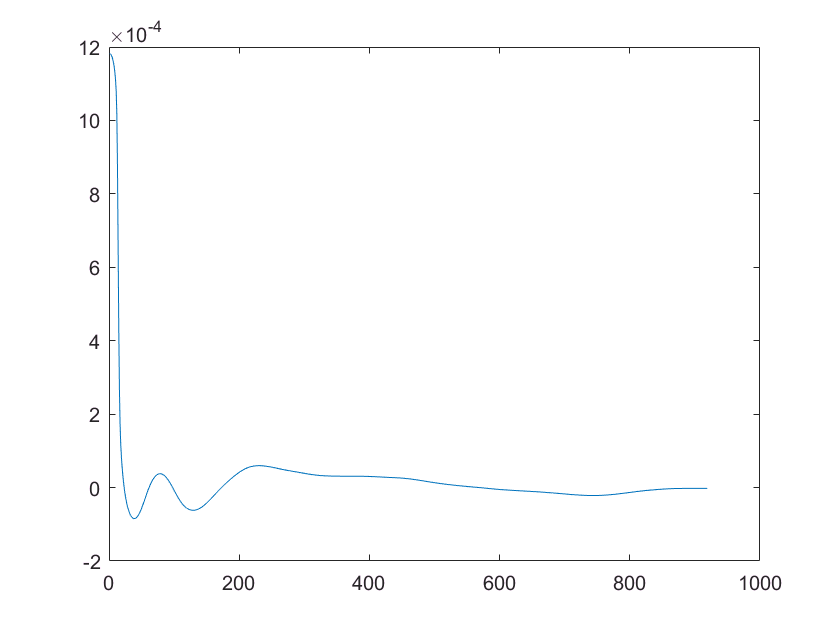

% try doing differentiation on the mean signal 

data_mean  = mean(data,2);
data_mean_d = TVRegDiff(data_mean,50,0.00002,[],'small',1e-6,0.01,0,0);
figure
plot(data_mean_d)

% some ideas from stavros cycle trigger stim
% 2 ms positive/negative voltage samples
% second derivative close ot zero (typo/ should be first?)
% difference etween sample with maximum deflection neighboring 2 samples before 

val = 0.
data_mean_find_zero = abs(data_mean_d);
[zero_1,ind_1] = min(data_mean_find_zero); 





[pks,locs,w,p]= findpeaks(data_mean((t>0.01 & t <0.05)),t(t>0.01 & t <0.05),'Annotate','extents','WidthReference','halfheight')

pks =    1.0e-04 *

    0.1930
    0.1916
    0.1910
    0.1902
    0.1892
    0.1889
    0.1869
    0.1863
    0.1836
    0.1836


locs =     0.0199    0.0202    0.0204    0.0206    0.0211    0.0213    0.0216    0.0220    0.0226    0.0228    0.0232    0.0235    0.0239    0.0242    0.0247    0.0250    0.0251    0.0254    0.0260    0.0262    0.0265    0.0270    0.0272    0.0274    0.0276    0.0282    0.0283    0.0290    0.0295    0.0301    0.0303    0.0305    0.0307    0.0310    0.0313    0.0316    0.0318    0.0320    0.0324    0.0326    0.0341    0.0346    0.0348    0.0350    0.0352    0.0357    0.0360    0.0361    0.0364    0.0365


w =    1.0e-03 *

    0.3277    0.1638    0.2458    0.4096    0.1638    0.4096    0.3277    0.6554    0.1638    0.3277    0.4096    0.3277    0.3277    0.4915    0.3277    0.1638    0.2458    0.5734    0.2458    0.3277    0.4096    0.1638    0.2458    0.2458    0.5734    0.1638    0.6554    0.4915    0.5734    0.2458    0.1638    0.1638    0.2371    0.3277    0.2458    0.3277    0.2458    0.3277    0.2185    0.1674    0.2028    0.4263    0.1638    0.2458    0.1638    0.4573    0.2458    0.2458    0.1638    0.2186


p =    1.0e-07 *

    0.1237
    0.0449
    0.1042
    0.0098
    0.2668
    0.3893
    0.0202
    0.3761
    0.0123
    0.1115


% average
figure
[pks,locs,w,p]= findpeaks(abs(data_mean),t_new,'Annotate','extents','WidthReference','halfprom','MinPeakDistance',0.005,'sortstr','descend','minpeakheight',20e-6)

pks =    1.0e-04 *

    0.6297
    0.5467
    0.4809


locs =     0.0187    0.0515    0.0093


w =     0.0096    0.0246    0.0027


p =    1.0e-04 *

    0.4866
    0.3704
    0.1756


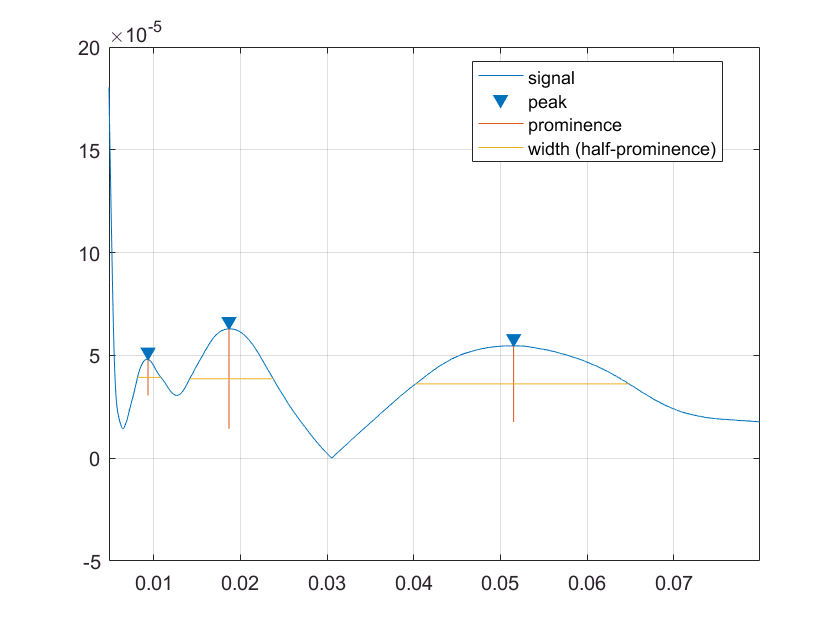

findpeaks(abs(data_mean),t_new,'Annotate','extents','WidthReference','halfprom','MinPeakDistance',0.005,'sortstr','descend','minpeakheight',20e-6)